### Gamma at origin

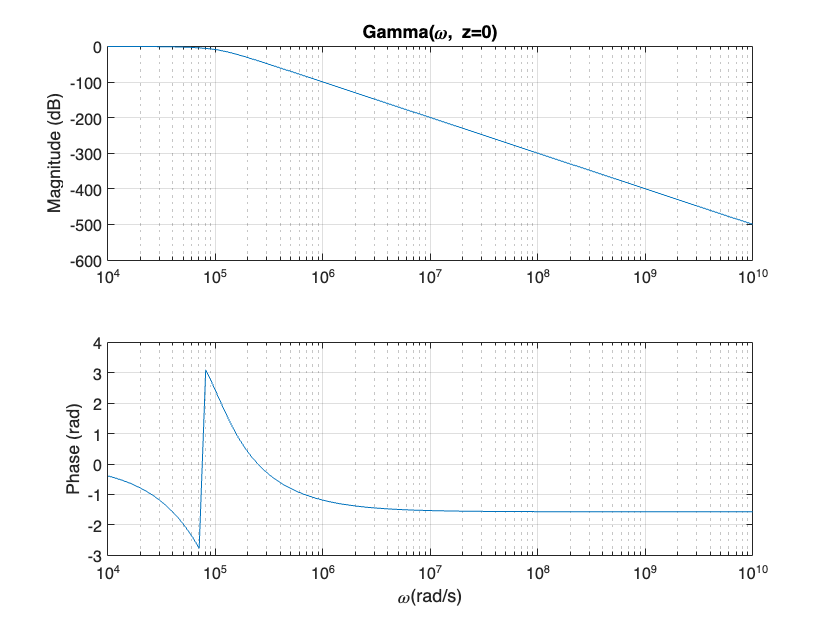

[b,a] = besself(5,1e5);
[Gamma0,w] = freqs(b,a,logspace(4, 10, 1e2));
figure;
plot_resp_logy(w, Gamma0, 'Gamma(\omega, z=0)')

### Finding S parameters - apply to an element

These parameters are when for line when all the switches are off

mu0 = 4*pi*1e-7;  % Value of mu_0 in N/A^2 (Tm/A)
epsilon0 = 8.8541878128e-12;  % Value of epsilon_0 in F/m
c = 3e8;

L = 200e-6;
W = 20e-6;
S = W;
Lstrip = 3e-6;
Sstrip = 1e-6;
Wstrip = 30e-6;

Rg = 50; % omega

N = 16; % number of switches
l = L/N;

coupledmicrostrip = coupledMicrostripLine(Length=200e-6, ...
                                            Width=20e-6, ...
                                            Spacing=20e-6, ...
                                            Height = 10e-6, ...
                                            GroundPlaneWidth=200e-6 ...
                                         )

coupledmicrostrip =   coupledMicrostripLine with properties:

              Length: 2.0000e-04
               Width: 2.0000e-05
             Spacing: 2.0000e-05
              Height: 1.0000e-05
    GroundPlaneWidth: 2.0000e-04
           Substrate: [1×1 dielectric]
           Conductor: [1×1 metal]


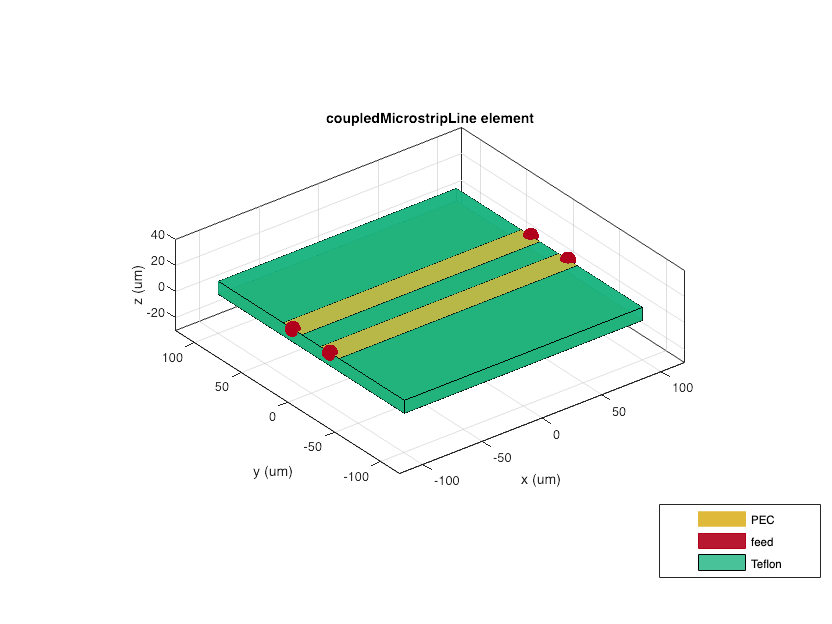

show(coupledmicrostrip)

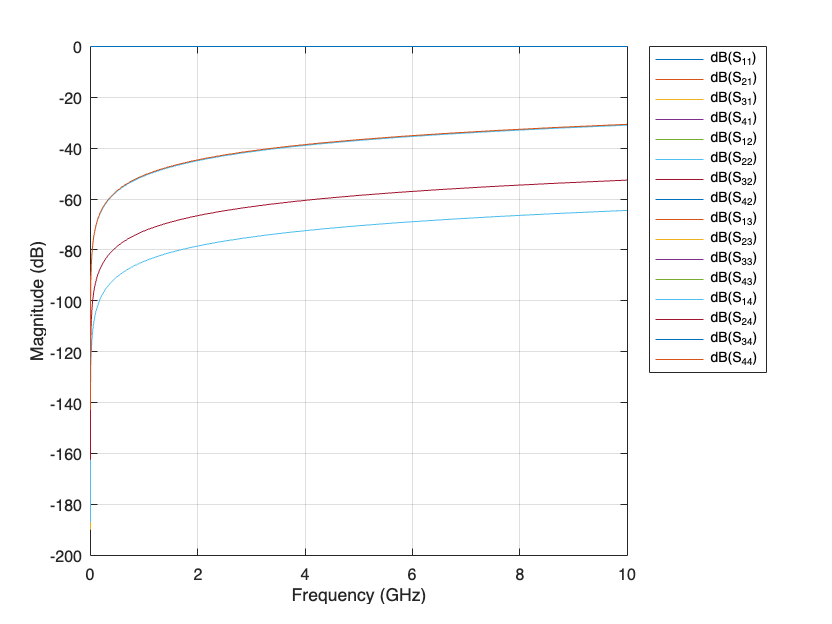


Sobj = sparameters(coupledmicrostrip, logspace(4, 10, 1e2));
rfplot(Sobj);


% extract the S parameters

S = Sobj.Parameters;  % Get the S-parameter matrix

S11 = S(1, 1, :);
S22 = S(2, 2, :);
S33 = S(3, 3, :);
S44 = S(4, 4, :);

S12 = S(1, 2, :);
S13 = S(1, 3, :);
S14 = S(1, 4, :);

S21 = S(2, 1, :);
S23 = S(2, 3, :);
S24 = S(2, 4, :);

S31 = S(3, 1, :);
S32 = S(3, 2, :);
S34 = S(3, 4, :);

S41 = S(4, 1, :);
S42 = S(4, 2, :);
S43 = S(4, 3, :);

% SA and SB

SA = cat(1, cat(2, S11, S12), cat(2, S21, S22));
SB = cat(1, cat(2, S13, S14), cat(2, S23, S24));

% Se and So

Se = SA - SB;
So = SA + SB;

### Odd Mode

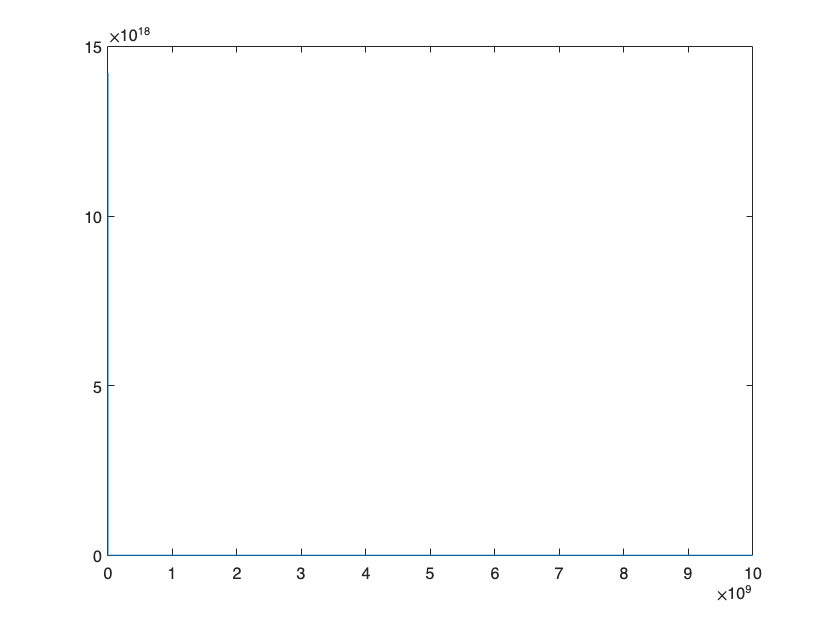

ABCDo = s2abcd(So);
Zo_o = sqrt(ABCDo(1, 1, :)./ABCDo(2, 2, :));
gamma_o = transpose(squeeze(acosh(ABCDo(1, 2, :))/l));

% parameters - odd
Ro = real(gamma_o.*Zo_o);
Lo = imag(gamma_o.*Zo_o);
Go = real(gamma_o./Zo_o);
Co = imag(gamma_o./Zo_o);

eps_ref_o = transpose((imag(gamma_o).*c)./w).^2;
figure;
plot(w, eps_ref_o)

### Even Mode

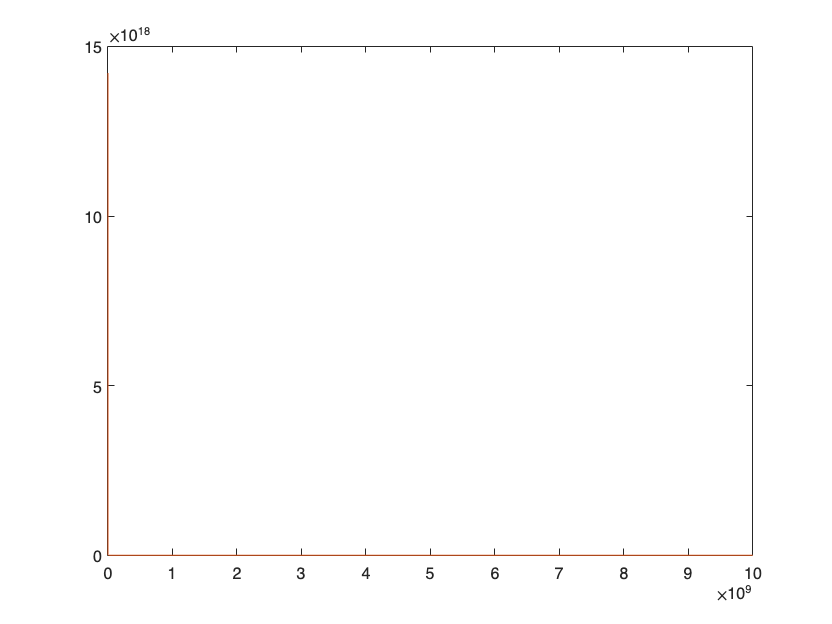

ABCDe = s2abcd(Se);
Zo_e = sqrt(ABCDe(1, 1, :)./ABCDe(2, 2, :));
gamma_e = squeeze(acosh(ABCDe(1, 2, :))/l);

% parameters - even
Re = real(gamma_e.*Zo_e);
Le = imag(gamma_e.*Zo_e);
Ge = real(gamma_e./Zo_e);
Ce = imag(gamma_e./Zo_e);

eps_ref_e = transpose(((imag(gamma_e).*c)./w).^2);
figure;
plot(w, eps_ref_e)

Functions

function plot_resp_logy(x, y, name) % plot functions with dB in y
    subplot(2, 1, 1)
    semilogx(x, 20*log(abs(y))/log(10))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_resp(x, y, name) % plot functions
    subplot(2, 1, 1)
    semilogx(x, abs(y))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_switch_comparison(w, Gamma0, Gamma_on, Gamma_off)
    subplot(3, 1, 1)
    semilogx(w, 20*log(abs(Gamma0))/log(10))
    ylabel("\Gamma(\omega, z=0)")
    grid("on")
    subplot(3, 1, 2)
    semilogx(w, 20*log(abs(Gamma_on))/log(10))
    ylabel("\Gamma_{on}(\omega)")
    grid("on")
    subplot(3, 1, 3)
    semilogx(w, 20*log(abs(Gamma_off))/log(10))
    ylabel("\Gamma_{off}(\omega)")
    grid("on")
    xlabel("\omega(rad/s)")
end